# Algorithms

[⇦ Overview](matlab: run("OpenOverview.m"))

The formal name for a clearly defined process that could be followed by a computer is an algorithm. You already know several algorithms from mathematics, and you may have encountered them elsewhere in your life as well for processes like searching for a word in a paper dictionary or sorting a hand of cards into a standard order. You may be less familiar with expressing algorithms themselves clearly and concisely.

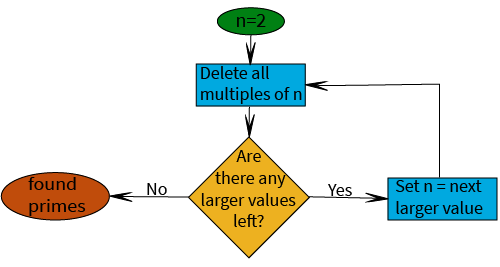

## Communicating Algorithms

There are many ways to express an algorithm, but the most common are to write out the procedure in standard sentences or in pseudocode. Pseudocode is a term that means a small collection of formal words and symbols that can be combined with formatting and small amounts of text to describe an algorithm that could be implemented in any programming language by a programmer who is familiar with the language.

### Common features of pseudocode

- A symbol that denotes that the rest of the line is a comment. Coming from a MATLAB environment, this script will use `%` as the comment character.

- `a `$\leftarrow$` b `means "a is assigned the value of b"

- Standard mathematical symbols such as +, *, < as well as mathematical symbols from discrete mathematics such as \ ("set difference"), ~ ("logical not"), & ("logical and"), and == ("logical equals").

- Sequence identification `startPoint to endPoint` means the set of value

`{startPoint, startPoint + 1, startPoint + 2, ..., endPoint - 2, endPoint -1, endPoint`}`. `

            Similarly, if the step size between values isn't 1, that can be indicated by 

`startPoint by stepSize to endPoint` 

            to mean the list of values 

`{startPoint, startPoint + stepSize, startPoint + 2*stepSize, ... , startPoint+m*stepSize}` 

            where (`endPoint-startPoint)/(m+1) < stepSize, but (endPoint-startPoint)/m `$\geq$ `stepSize.`

          5. Standard control logic:` while, for, if/else. `

### Example: Expressing the Simple Square Chaos Game as an Algorithm

`startingPoint `$\leftarrow$` random point`

`numPts `$\leftarrow$` number of iterations`

`for k = 1 to numPts`

`    newCorner `$\leftarrow$` randomly selected corner coordinates`

`    nextPoint `$\leftarrow$` startingPoint + (newCorner-startingPoint)/2`

`    Graph nextPoint`

`    startingPoint `$\leftarrow$ `nextPoint`

## Coding a Simple Math Problem

What are all the primes less than or equal to 100? This is a computationally straight-forward problem with several common algorithmic solutions. A positive integer $n$ is prime if its only factors are $1$ and $n$. 

**Algorithm 1:  **Iteratively build the list of all primes less than or equal to $n$ up to `maximumValue`

    `% Recognize that 2 is the smallest prime. `

    `% When n=2, the only prime less than or equal to n is `$2$`.`

`    primeList `$\leftarrow$` 2`

`    for n in 3 to maximumValue`

`            for p in primeList`

`                if n `[`mod`](https://www.mathworks.com/help/matlab/ref/mod.html)` p == 0`

`                    n is composite and can be ignored`

`                else if no primes in primeList are factors of n`

`                    append n to primeList`

primeList = 2;
for n = 3:100
    notPrimeFlag = 0;
    for p = primeList
        if mod(n,p) == 0
            notPrimeFlag = 1;
        elseif p == primeList(end) && notPrimeFlag == 0
            primeList = [primeList n];
        end
    end
end
primeList

**Algorithm 2:** Assume all numbers are possible up to `maximumValue`, then iteratively eliminate multiples of smaller values.

`        primeList `$\leftarrow$` 2 to maximumValue`

`        p `$\leftarrow$` 2`

`        index `$\leftarrow$` 1`

`        while p < sqrt(maximumValue)`

`            primeList `$\leftarrow$` primeList \ (2*p by p to maximumValue)`

`            index `$\leftarrow$` index + 1`

`            p `$\leftarrow$` primeList(index)`

** Exercise 1**.

    a) Implement Algorithm 2. 

    b) Time how long Algorithm 1 and Algorithm 2 take to determine all the primes up to 100. Which implementation is more efficient? Why?

    c) Time how long Algorithm 1 and Algorithm 2 take to determine all the primes up to 10,000. Which implementation is more efficient? Why?

  **Pro-tip**. Remember that you can use the documentation to search for functions, optional arguments, and syntax. Try a couple of options here such as the general web search:

Or a specific local documentation search such as:

The challenge is if you don't remember standard terminology, in which case searching may be awkward or impossible until you can determine what other people call whatever you are looking for.

% Code your solution to Exercise 1 here

primeList

### Testing and Proof of Correctness

While the unavoidable test of correctness for code is whether it compiles and runs, it is also important to ensure that it correctly implements the algorithm, and that the algorithm solves the problem it is intended to solve. In fact, there is an error in either Algorithm 1 or Algorithm 2. 

** Exercise 2**.

Use both Algorithm 1 and Algorithm 2 to compute the primes less than or equal to 25. Do you get the same result? If not, what is the difference and why? How do you fix the appropriate algorithm? What does that do to your code?

#### Unit Testing

By breaking down your code into simple components where you can check if the input and outputs match what you expect, you can formally or informally check that your code behaves correctly. This can also help in isolating the cause of a bug that you know about but haven't determined a fix for yet. If we consider the implementation of Algorithm 1, then the smallest units would be individual lines such as

or

and running the unit test could be simply running the code with that line unsuppressed, or if you don't have the whole program built yet you can run the unit test by defining the values that will come in and running the unit test to see what comes out. 

% Set values for testing
primeList = [2 3 5 7];
n = 11;

% Expected Result?
primeListExpected = [2 3 5 7 11]

% Run test
primeList = [primeList n]

For larger programs or outputs, you might not want to check by hand. In general, high level programming languages have built-in functions to help with testing such as the ability to throw an exception by responding to particular types of errors with a standard message or by documenting assumptions within your code with assertions. 

assert(isequal(primeList,primeListExpected))

  **Try**. Modify the code above so that `primeList` does not match `primeListExpected` and run the code again. What happens now?

In the case of a branch or a loop, you want to test that the logic follows the path you were planning by setting up input values leading to each path through the code. 

#### Edge Cases

One common class of programming errors are those that arise along boundaries. Did you check what happens at very large or very small values? What about 0, which is the boundary between positive and negative numbers? Are there any inequalities? Should they be strict or not? 

### **Application: Caesar Cipher**

`pleaseCodeThis(InputString,InShift)` is a function that takes a string and a shift and implements the Caesar cipher which shifts each letter of the alphabet forward (or backward) by `InShift` places. Historically, this was commonly implemented with nested disks. In the model below, the outer ring is fixed and the inner ring can spin. 

  **Try**. Run the code below with different arguments by changing the value of the slider. 

shift = 20;
caesarCipherTool(shift)

pleaseCodeThis("Once upon a time...",shift)

** Exercise 3**.

The function `pleaseCodeThis` only works in some cases. For what values does it fail and why? Explain how you would fix it. 

## **Application: Visual Cryptography**

Consider the following example black and white images stored in `m1` and `m2` by running the code block below. Do you see any patterns?

load("EncryptedImage.mat")
imshow(m1)
imshow(m2)

Now consider the following image created by subtracting the two matrices and taking the absolute value. Do you see any patterns?

imshow(abs(m1-m2))

  **Try**.

- What happens if you use `imshow` on the matrix `m1-m2` without the absolute value?

- What happens if you use `imshow` on the matrix `m1+m2`? Does this change with an absolute value?

 **Reflect**.

- Why do you think this happens? 

- What is the difference between adding and subtracting?

** Exercise 4**.

Implement a simple visual cryptography algorithm that transforms a black and white image into two chaotic-appearing images that are in fact carefully balanced compositions with equal numbers of white pixels and black pixels. Briefly, replace each white pixel with four new pixels in each cryptographically transformed image-pair:

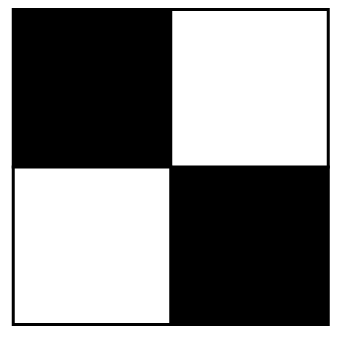   and                   or                  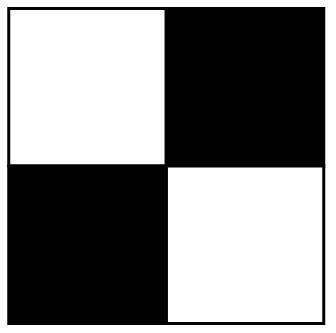   and   ,

and replace each black pixel in the original image similarly with either

   and                   or                     and   .

When recombined, tracking only the black pixels, note that the white regions are now exactly 50% white pixels and 50% black pixels in random combinations that will appear to the eye as grey at sufficient scale. The black regions are preserved. This also makes it possible to rescale and recolor back to the original image with complete fidelity if desired.

**Simple Visual Cryptography Algorithm**

`startingImage `$\leftarrow$` matrix of 1's and 0's`

`sx `$\leftarrow$` number of rows in startingImage`

`sy `$\leftarrow$` number of columns in startingImage`

`Initialize two matrices, im1 and im2 of size 2*sx by 2*sy`

`for j = 1 to sx`

`    for k = 1 to sy`

`        flip = random choice of 0 or 1`

`        if startingImage(j,k) == 1 `

`            if flip == 0`

`                im1(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [1 0;0 1]`

`                im2(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [0 1;1 0]`

                        `else`

                        `    im2(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [1 0;0 1]`

`                im1(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [0 1;1 0]`

`        else`

`            if flip == 0`

`                im1(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [1 0;0 1]`

`                im2(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [1 0;0 1]`

                        `else`

                        `    im2(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [0 1;1 0]`

`                im1(2*j-1:2*j,2*k-1:2*k) `$\leftarrow$` [0 1;1 0]`                      

Implement this algorithm. Test your results on the following images you have already played with:

% Clear the workspace of all current variables
clear
% Load sample images
load("BW_Images.mat")
% Print a list of images that are now in the workspace
whos

% Select an image and call it im0

% Code solution to Exercise 4 here to transform im0 into two images im1 and
% im2 using the visual cryptography algorithm given

% Uncomment the line below to show your results
% montage({im0,abs(im1-im2),im1,im2})

 **Reflect**.

- Does visual cryptography only apply to black and white images? 

- Can you sketch an algorithm that would encrypt an image in color? 

- If you have more range to work with (grayscale or color) can you sketch an algorithm that would encrypt an image inside a single image rather than requiring a pair? 

- What uses are there for visual cryptography? 

[⇦ Overview](matlab: run("OpenOverview.m"))

## Helper Functions

#### pleaseCodeThis(InputString,InShift)

function OutString = pleaseCodeThis(InputString,InShift)
% Convert the InputString to ASCII
numString = int8(char(InputString));
OutString = numString;
bdryVals = int8('azAZ');
% Check that the input character is a letter and if so, encode it
% appropriately
for k = 1:length(numString)
    if (numString(k) >= bdryVals(1) && numString(k) <= bdryVals(2))||(numString(k) >= bdryVals(3) && numString(k) <= bdryVals(4))
        OutString(k) = numString(k)+InShift;
    end
end
% Convert the ASCII back to a string
OutString = convertCharsToStrings(char(OutString));
end

#### Image generation code

function caesarCipherTool(shift)
try
    % Check that shift is an integer
    assert(round(shift)==shift);
    assert(regexp(string(shift),"[0-9].*"));

    figure
    % Draw and shade the relevant circles
    rectangle("Position",[-1 -1 2 2],"Curvature",[1 1])
    rectangle("Position",[-.75 -.75 1.5 1.5],"Curvature",[1 1],"FaceColor",[.9 .9 .9])
    rectangle("Position",[-.5 -.5 1 1],"Curvature",[1 1],"FaceColor","w")
    % Set up the angular step size required for displaying the alphabet
    dtheta = 360/26;
    % Turn off the x and y axes and make the circles round
    axis square off
    hold on
    alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';
    for k = 1:26
        % Use a fixed width font so that each letter is centered in its section
        text(0.9*sind((k-1)*dtheta),0.9*cosd((k-1)*dtheta),alphabet(k), ...
            "Rotation",(1-k)*dtheta,"FontName","FixedWidth","FontWeight","bold");
        text(0.6*sind((k-shift-1)*dtheta),0.6*cosd((k-shift-1)*dtheta),alphabet(k), ...
            "Rotation",(1-k+shift)*dtheta,"FontName","FixedWidth","FontWeight","bold");
        % Plot dividing lines; shift by 3/5*dtheta to account for the width of the letters
        plot([-sind((k-3/5)*dtheta) -0.5*sind((k-3/5)*dtheta)], ...
            [cosd((k-3/5)*dtheta) 0.5*cosd((k-3/5)*dtheta)], ...
            "Color",[0 0.4470 0.7410])
    end
    hold off
catch
    % If an assertion failed, display a warning and do not try to run the
    % rest of the code
    warning("Shifting by a non-integer value may not generate a useable code.")
end
end
